clearvars; close all; clc;

# Closed box including ANSYS imported results

2024-06-07, JVsound, J.G. Vermond

## Introduction

A closed box system (and all other loudspeaker systems in the toolbox) can be simulated in different ways:

- Lumped and analytical elements: this can be done using only the toolbox

- Lumped elements for the electrical and mechanical part of the system, and import the acoustic impedances from an FEA (ANSYS) simulation. The resulting sound pressure level in the far-field is calculated by the toolbox.

- Equal to 2, only the sound pressure level is also calculated by imported results from ANSYS.

This livescript shows how the above is carried out, and will validate the results.

## Validation by Hornresp

We load some results (see Appendix A for the Hornresp inputs) exported by Hornresp to validate our results.

load closedboxvalspl.mat

## Driver

The driver for this simulation is the B&C 18SW115-8.

% Create woofer object:
wf			= speaker.woofer;
wf.brand	= "B&C";
wf.model	= "18SW115-8";
wf.size		= 18;

wf.re		= 5.3;
wf.qes		= 0.32;
wf.qms		= 5.6;
wf.fs		= 32;
wf.sd		= 1210e-4;
wf.vas		= 187e-3;

wf.le		= 1.9e-3;
wf.xmax		= 14e-3;
wf.paes		= 1700

wf =   woofer with properties:

    brand: "B&C"
    model: "18SW115-8"
     size: 18
       re: 5.3000
      qes: 0.3200
      qms: 5.6000
       fs: 32
       sd: 0.1210
      vas: 0.1870
       le: 0.0019
     xmax: 0.0140
     paes: 1700
      qts: 0.3027
      cms: 9.1045e-05
      kms: 1.0984e+04
      mms: 0.2717
      mmd: 0.2241
      rms: 9.7550
       bl: 30.0795
        a: 0.1963


## Simulation 1

Create a simulation object:

% Simulation object:
sim1		= acoustics.simulation;

% Assign frequencies:
sim1.f		= logspace(1,log10(2e4),1e3);

% Generator voltage:
sim1.eg		= 2.83;

% Distance to mic [m]:
sim1.r		= 1;

### Enclosure

Create an enclosure object with an internal volume of 150L.

% Enclosure object:
encl1		= enclosure.closedbox;

% Internal volume [m3]:
encl1.vol	= 150e-3;

### Results

Assign the enclosure and driver to the simulation object:

sim1.encl	= encl1;
sim1.sp		= wf;

The results are shown in the following figures:

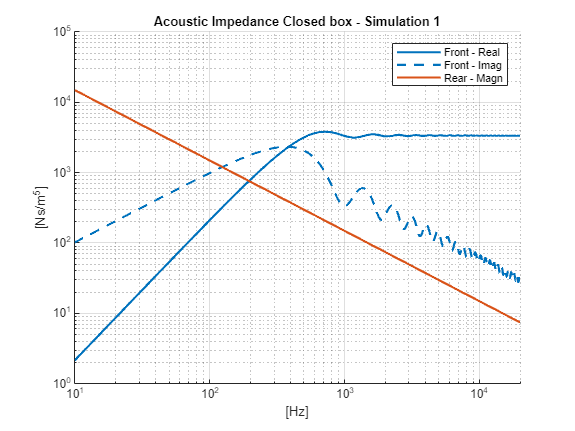

% Get SPL and Za:
spl			= sim1.spl;
za			= sim1.za;

% Figure 1 - Acoustic impedance
fig1				= figure;
ax1					= axes(fig1); hold on; grid on;
ax1.FontSize		= 8;
ax1.XScale			= "log";
ax1.XLim 			= [sim1.f(1) sim1.f(end)];
ax1.YScale			= "log";
ax1.Title.String	= "Acoustic Impedance Closed box - Simulation 1";
ax1.XLabel.String	= "[Hz]";
ax1.YLabel.String	= "[Ns/m^5]";

p1	= plot(ax1,sim1.f,real(za.front),LineWidth=1.5);
plot(ax1,sim1.f,imag(za.front),LineWidth=1.5,LineStyle="--",Color=p1.Color);

ax1.ColorOrderIndex = 2;

plot(ax1,sim1.f,abs(za.rear),LineWidth=1.5);

leg1		= legend(ax1,"Front - Real","Front - Imag","Rear - Magn");

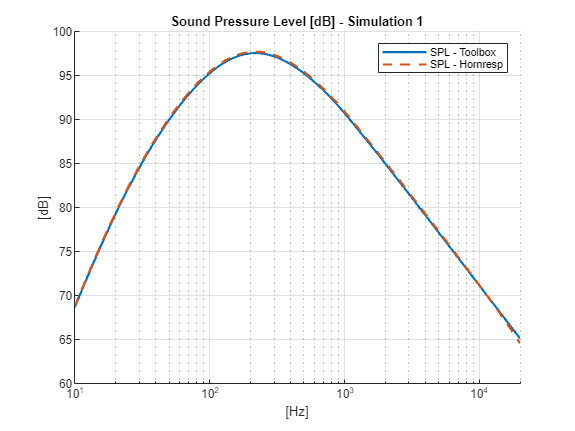


% Figure 2 - SPL
fig2				= figure;
ax2					= axes(fig2); hold on; grid on;
ax2.FontSize		= 8;
ax2.XScale			= "log";
ax2.XLim 			= [sim1.f(1) sim1.f(end)];
ax2.XLabel.String	= "[Hz]";
ax2.YLabel.String	= "[dB]";
ax2.Title.String	= "Sound Pressure Level [dB] - Simulation 1";

plot(ax2,sim1.f,spl,LineWidth=1.5);
plot(ax2,closedboxvalspl.Freqhertz,closedboxvalspl.SPLdB,LineWidth=1.5,LineStyle="--");

leg2 		= legend(ax2,"SPL - Toolbox","SPL - Hornresp");

The results are almost identical. The minor deviation is probably due to a different sound velocity and/or density of air.

## Simulation 2

This simulation is identical to simulation 1, only the acoustic impedance is imported from an ANSYS FEA model.

We copy the simulation object:

% Simulation 2 object:
sim2 		= sim1;

### Acoustic impedance by ANSYS

## Simulation 3

## Appendix A - Hornresp inputs

To validate the results in this Livescript it is compared to results by hornresp: